# Hurricane Harvey Weather Event

## Background and Scope

This report provides insight into the damages caused by hurricane Harvey in the summer of 2017. The objective is to identify the areas most impacted by the hurricane as well as the total property damage.

### Import data from text file

Script for importing data from the following text file:

Setup the Import Options and import the data:

opts = delimitedTextImportOptions("NumVariables", 24);


Specify range and delimiter

opts.DataLines = [2, Inf];
opts.Delimiter = ",";


Specify column names and types

opts.VariableNames = ["EpisodeID", "Event_ID", "State", "Year", "Month", "Event_Type", "CZ_Name", "Begin_Date_Time", "Timezone", "End_Date_Time", "Injuries_Direct", "Injuries_Indirect", "Deaths_Direct", "Deaths_Indirect", "Damage_Property", "Property_Cost", "Damage_Crops", "Crop_Cost", "Begin_Lat", "Begin_Lon", "End_Lat", "End_Lon", "Episode_Narrative", "Event_Narrative"];
opts.VariableTypes = ["double", "double", "categorical", "double", "categorical", "categorical", "categorical", "datetime", "double", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "char"];


Specify file level properties

opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";


Specify variable properties

opts = setvaropts(opts, "Event_Narrative", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["State", "Month", "Event_Type", "CZ_Name", "Episode_Narrative", "Event_Narrative"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Begin_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "End_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "ThousandsSeparator", ",");


Import the data

StormEvents = readtable("C:\DataScience\Exploratory Data Analysis\StormEvents\StormEvents_2017_finalProject.csv", opts);

Clear temporary variables

clear opts

### Property Damage by State

Filter data for:

- The relevant dates for weather events related to hurricane Harvey

- The states affected by hurricane Harvey

Start = datetime("2017-08-16 23:59:59");
Finish = datetime("2017-09-04 00:00:00");
AllStateIdx = StormEvents.Begin_Date_Time > Start & StormEvents.End_Date_Time < Finish & (StormEvents.State == "ARKANSAS" | StormEvents.State == "KENTUCKY" | StormEvents.State == "LOUISIANA" | StormEvents.State == "MISSISSIPPI" | StormEvents.State == "NORTH CAROLINA" | StormEvents.State == "TENNESSEE" | StormEvents.State == "TEXAS");
StormEventsStates = StormEvents(AllStateIdx,:);
StateCost = groupsummary(StormEventsStates,"State",'sum','Property_Cost');
StateCost = sortrows(StateCost,"sum_Property_Cost","descend")

StateCost = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                272           7.7427e+10    
    LOUISIANA             85           7.5277e+07    
    NORTH CAROLINA        59           1.2339e+07    
    MISSISSIPPI           39             9.15e+05    
    TENNESSEE             46             5.04e+05    
    KENTUCKY              20             4.35e+05    
    ARKANSAS              52                61000    


This bar plot shows the total property damage cost by state for the states affected by the hurricane:

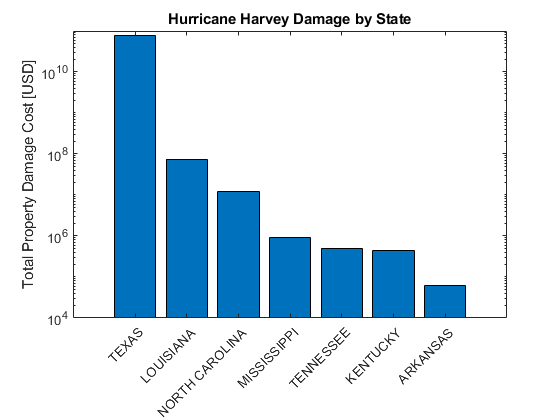

figure
bar(StateCost.sum_Property_Cost)
set(gca,'XTick',1:7,'XTickLabel',StateCost.State,'YScale','log')
xtickangle(45)
ylabel('Total Property Damage Cost [USD]')
title('Hurricane Harvey Damage by State')

The bar plot shows that Texas and Louisiana sustained the highest total property damage costs.

### Events for Texas and Louisiana

This section identifies the types of weather events with the highest number of occurrences in the two states with the highest total property damage cost.

Start = datetime("2017-08-16 23:59:59");
Finish = datetime("2017-09-04 00:00:00");
TXLAIdx = StormEvents.Begin_Date_Time > Start & StormEvents.End_Date_Time < Finish & (StormEvents.State == "LOUISIANA" | StormEvents.State == "TEXAS");
StormEventsTXLA = StormEvents(TXLAIdx,:);
StormEventsTXLAs = groupsummary(StormEventsTXLA,"Event_Type",'sum','Property_Cost');
StormEventsTXLAs = sortrows(StormEventsTXLAs,"GroupCount","descend")

StormEventsTXLAs = 11×3 table
       Event_Type        GroupCount    sum_Property_Cost
    _________________    __________    _________________

    Flash Flood             179           4.3615e+10    
    Tropical Storm           44           2.9117e+10    
    Tornado                  33           7.8275e+06    
    Heat                     30                    0    
    Thunderstorm Wind        27                65500    
    Flood                    17            8.875e+07    
    Storm Surge/Tide         10           5.3202e+08    
    Hurricane                 9           4.1411e+09    
    Funnel Cloud              3                    0    
    Hail                      3                    0    
    Heavy Rain                2                    0    


By far the most widespread weather event during the hurricane was flash flooding.

## Visualizations

### Event Occurrences

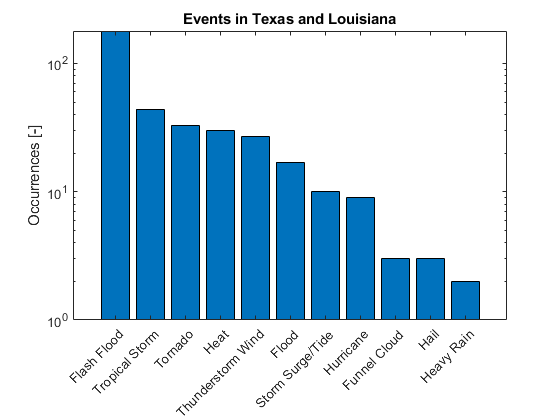

bar(StormEventsTXLAs.GroupCount)
set(gca,'XTick',1:height(StormEventsTXLAs),'XTickLabel',StormEventsTXLAs.Event_Type,'YScale','log')
xtickangle(45)
ylabel('Occurrences [-]')
title('Events in Texas and Louisiana')

### Event Locations

This section graphically shows where weather events occurred in the two states with the highest total property damage cost.

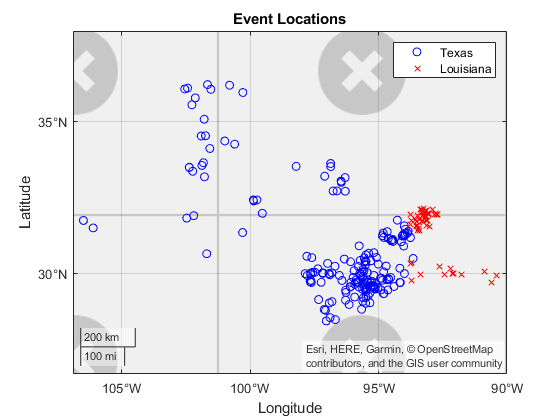

StormEventsTXLA.meanLat = (StormEventsTXLA.Begin_Lat + StormEventsTXLA.End_Lat)/2;
StormEventsTXLA.meanLon = (StormEventsTXLA.Begin_Lon + StormEventsTXLA.End_Lon)/2;
StormEventsTX = StormEventsTXLA((StormEventsTXLA.State == "TEXAS"),:);
StormEventsTXflood = StormEventsTXLA((StormEventsTXLA.State == "TEXAS" & (StormEventsTXLA.Event_Type == "Flash Flood" | StormEventsTXLA.Event_Type == "Flood")),:);
StormEventsLA = StormEventsTXLA((StormEventsTXLA.State == "LOUISIANA"),:);
figure
geobasemap satellite
geoscatter(StormEventsTX.meanLat,StormEventsTX.meanLon,'bo')
hold on
geoscatter(StormEventsLA.meanLat,StormEventsLA.meanLon,'rx')
title('Event Locations')
legend('Texas','Louisiana')

## Analysis

### Property Damage by County

This section identifies the three counties in each state with:

- The highest number of weather events

- The highest total property damage cost

#### Counties in Louisiana with the highest number of weather events:

LACountiesEvents = sortrows(groupsummary(StormEventsLA,"CZ_Name",'sum',"Property_Cost"),"GroupCount","descend");
LACountiesEventsTop = LACountiesEvents(1:3,:)

LACountiesEventsTop = 3×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    NATCHITOCHES        21                0        
    SABINE              15                0        
    RED RIVER            9                0        


#### Counties in Louisiana with the highest total property damage cost:

LACountiesCosts = sortrows(groupsummary(StormEventsLA,"CZ_Name",'sum','Property_Cost'),"sum_Property_Cost","descend");
LACountiesCostsTop = LACountiesCosts(1:3,:)

LACountiesCostsTop = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1                6e+07     
    BEAUREGARD        1              1.5e+07     
    ACADIA            1                2e+05     


#### Counties in Texas with the highest number of weather events:

TXCountiesEvents = sortrows(groupsummary(StormEventsTX,"CZ_Name",'sum',"Property_Cost"),"GroupCount","descend");
TXCountiesEventsTop = TXCountiesEvents(1:3,:)

TXCountiesEventsTop = 3×3 table
     CZ_Name     GroupCount    sum_Property_Cost
    _________    __________    _________________

    HARRIS           21           1.0001e+10    
    GALVESTON        17                2e+10    
    FORT BEND        13           1.6004e+10    


#### Counties in Texas with the highest total property damage cost:

TXCountiesCosts = sortrows(groupsummary(StormEventsTX,"CZ_Name",'sum','Property_Cost'),"sum_Property_Cost","descend");
TXCountiesCostsTop = TXCountiesCosts(1:3,:)

TXCountiesCostsTop = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17                2e+10    
    FORT BEND         13           1.6004e+10    
    MONTGOMERY         6              1.4e+10    


## Conclusions

The insurance company should send more people to Texas than Louisiana.  There were a small number of weather events in Louisiana resulting in a large amount of property damage.  The counties in Louisiana with the largest number of events actually did not experience any property damage.

Galveston and Fort Bend counties in Texas made both the highest occurrence and highest damage lists. A larger number of people should be sent to these two counties.